**Linear Support Vector Machine - Primal Model**

Find the separating hyperplane with maximum margin for the data set given by A and B values:

close all;
clear;
clc;

matlab.lang.OnOffSwitchState = 1;

A=[ 0.4952    6.8088    
    2.6505    8.9590    
    3.4403    5.3366    
    3.4010    6.1624    
    5.2153    8.2529    
    7.6393    9.4764    
    1.5041    3.3370    
    3.9855    8.3138    
    1.8500    5.0079    
    1.2631    8.6463    
    3.8957    4.9014    
    1.9751    8.6199    
    1.2565    6.4558    
    4.3732    6.1261    
    0.4297    8.3551    
    3.6931    6.6134    
    7.8164    9.8767    
    4.8561    8.7376    
    6.7750    7.9386    
    2.3734    4.7740 
    0.8746    3.0892  
    2.3088    9.0919   
    2.5520    9.0469  
    3.3773    6.1886  
    0.8690    3.7550   
    1.8738    8.1053   
    0.9469    5.1476   
    0.9718    5.5951   
    0.4309    7.5763   
    2.2699    7.1371 ];

B=[7.2450    3.4422
   7.7030    5.0965 
   5.7670    2.8791 
   3.6610    1.5002  
   9.4633    6.5084
   9.8221    1.9383 
   8.2874    4.9380 
   5.9078    0.4489 
   4.9810    0.5962 
   5.1516    0.5319 
   8.4363    5.9467  
   8.4240    4.9696  
   7.6240    1.7988
   3.4473    0.2725 
   9.0528    4.7106  
   9.1046    3.2798   
   6.9110    0.1745  
   5.1235    3.3181  
   7.5051    3.3392  
   6.3283    4.1555   
   6.1585    1.5058
   8.3827    7.2617 
   5.2841    2.7510 
   5.1412    1.9314
   6.0290    1.9818  
   5.8863    1.0087  
   9.5110    1.3298 
   9.3170    1.0890  
   6.5170    1.4606   
   9.8621    4.3674]; 

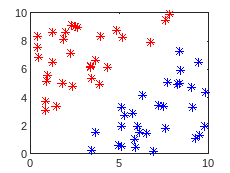

% Show values distribution
xlim = ([0 10]);
ylim = ([0 10]);
plot(A(:,1), A(:,2), "r*", B(:,1), B(:,2), "b*");

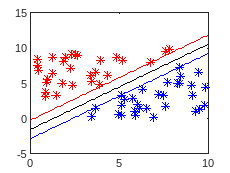

% Training Set
T = [A;B];

% Set Values
nA = size(A,1);
nB = size(B,1);

Q = [1 0 0
     0 1 0
     0 0 0];

D = [-A -ones(nA,1)
      B  ones(nB,1)];

d = -ones(nA+nB, 1);

f = zeros(3,1);

% Set Problem
options = optimset("LargeScale", "off", "Display", "off");
lambda = quadprog(Q,f,D,d,[],[],[],[],[],options);

% Set w and b
w = lambda(1:2);
b = lambda(3);

% Plot with the Max Margins 
x = 0:0.1:10;
u = (-w(1)/w(2)).*x - b/w(2);
v = (-w(1)/w(2)).*x + (1-b)/w(2);
vv = (-w(1)/w(2)).*x + (-1-b)/w(2);

plot(A(:,1), A(:,2), "r*", B(:,1), B(:,2), "b*");
hold on
xlim = ([0 10]);
ylim = ([0 10]);
plot(x,u, "k-", x,v,"r-", x,vv, "b-");